# Simulação 21

## **Trajetória de referência**

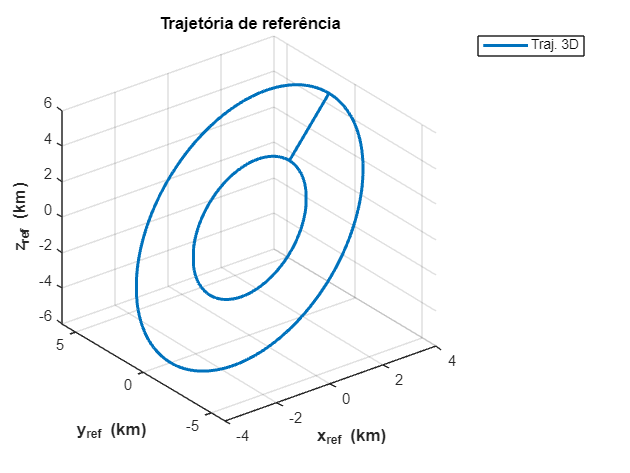

if isempty(tf)
    tf = 68124;
    t_man = tf/2;
    orb = 12;
    step_modelo = 0.01;
end

datax = Out(1).Simulation.x_ref;
datay = Out(1).Simulation.y_ref;
dataz = Out(1).Simulation.z_ref;
plot3(datax/10^3,datay/10^3,dataz/10^3,LineWidth=2);
title('Trajetória de referência');
xlabel('x_{ref} (km)','LineWidth',2,'Fontweight','bold');
ylabel('y_{ref} (km)','LineWidth',2,'Fontweight','bold');
zlabel('z_{ref} (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. 3D');
grid;

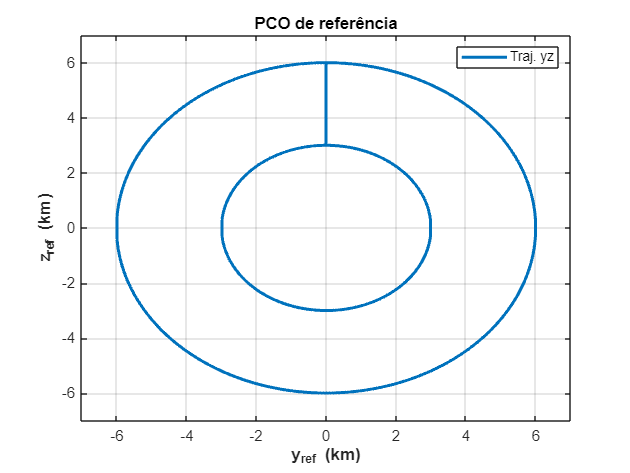

figure
datax = Out(1).Simulation.y_ref/10^3;
datay = Out(1).Simulation.z_ref/10^3;
plot(datax,datay,LineWidth=2);
title('PCO de referência');
xlabel('y_{ref} (km)','LineWidth',2,'Fontweight','bold');
ylabel('z_{ref} (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. yz');
xlim([-7 7]);
ylim([-7 7]);
grid;

%datax = Out(1).Simulation.tout;
datax = Out(1).Simulation.tout/(tf/orb);
datay = sqrt(Out(1).Simulation.x_ref.^2 + Out(1).Simulation.y_ref.^2 + Out(1).Simulation.z_ref.^2);
plot(datax,datay/10^3,LineWidth=2);
title('Trajetória de referência absoluta');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('Posição absoluta (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. Abs.');
grid;

## **Trajetória real**

figure
datax = Out(1).Simulation.x;
datay = Out(1).Simulation.y;
dataz = Out(1).Simulation.z;
plot3(datax/10^3,datay/10^3,dataz/10^3,LineWidth=2,Color="#459145");
title('Trajetória real');
xlabel('x (km)','LineWidth',2,'Fontweight','bold');
ylabel('y (km)','LineWidth',2,'Fontweight','bold');
zlabel('z (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. 3D');
grid;

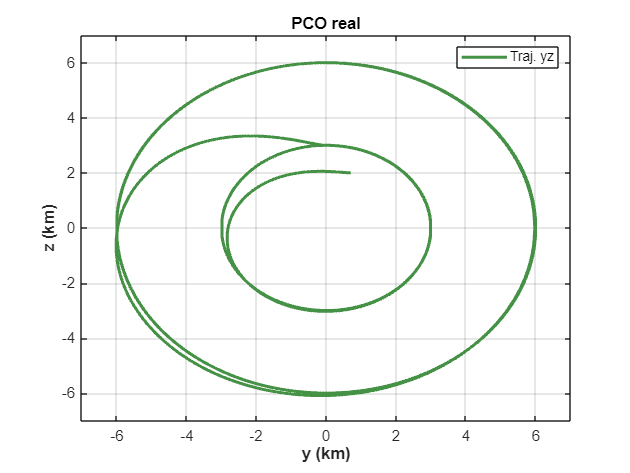

figure
datax = Out(1).Simulation.y/10^3;
datay = Out(1).Simulation.z/10^3;
plot(datax,datay,LineWidth=2,Color="#459145");
title('PCO real');
xlabel('y (km)','LineWidth',2,'Fontweight','bold');
ylabel('z (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. yz');
xlim([-7 7]);
ylim([-7 7]);
grid;

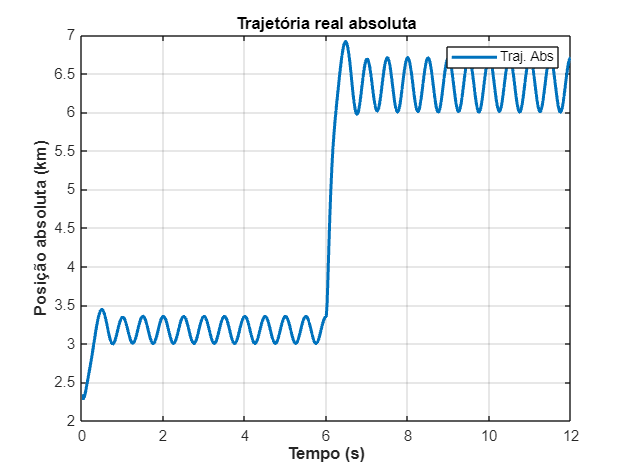



figure
%datax = Out(1).Simulation.tout;
datax = Out(1).Simulation.tout/(tf/orb);
datay = sqrt(Out(1).Simulation.x.^2 + Out(1).Simulation.y.^2 + Out(1).Simulation.z.^2);
plot(datax,datay/10^3,LineWidth=2);
title('Trajetória real absoluta');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
ylabel('Posição absoluta (km)','LineWidth',2,'Fontweight','bold');
legend('Traj. Abs');
grid;

## **Forças demandadas**

% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fx_b_dem;
% plot(tempo,datax,LineWidth=2);
% title('Força x');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força x (N)');
% legend('Força demandada x');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fy_b_dem;
% plot(tempo,datax,LineWidth=2);
% title('Força y');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força y (N)');
% legend('Força demandada y');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fz_b_dem;
% plot(tempo,datax,LineWidth=2);
% title('Força z');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força z (N)');
% legend('Força demandada z');
% grid;

## **Forças entregues**

% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fx_b_pro;
% plot(tempo,datax);
% title('Força x');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força x (N)');
% legend('Força demandada x');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fy_b_pro;
% plot(tempo,datax);
% title('Força y');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força y (N)');
% legend('Força demandada y');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out(1).Simulation.Fz_b_pro;
% plot(tempo,datax);
% title('Força z');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Força z (N)');
% legend('Força demandada z');
% grid;

## **Torques demandados**

% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out.Simulation.Mts_x;
% plot(tempo,datax);
% title('Torque x');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Torque x (Nm)');
% legend('Torque demandado x');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out.Simulation.Mts_y;
% plot(tempo,datax);
% title('Torque y');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Torque y (Nm)');
% legend('Torque demandado y');
% grid;
% 
% figure
% %tempo = Out(1).Simulation.tout/(tf/orb);
% tempo = Out(1).Simulation.tout;
% datax = Out.Simulation.Mts_z;
% plot(tempo,datax);
% title('Torque z');
% %xlabel('Órbitas');
% xlabel('tempo(s)');
% ylabel('Torque z (Nm)');
% legend('Torque demandado z');
% grid;

## **Erros Orbital**

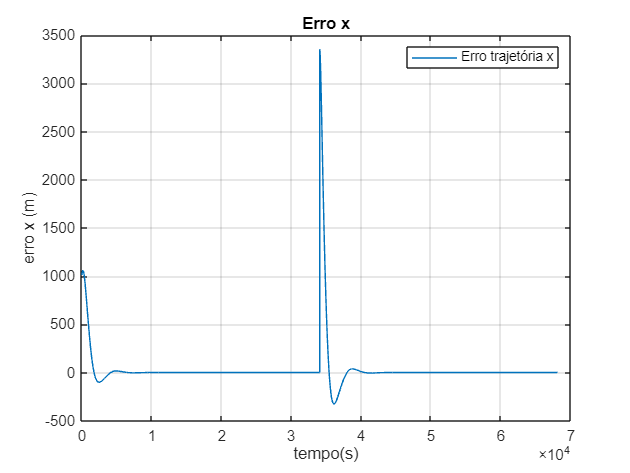

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.x_ref - Out(1).Simulation.x;
plot(tempo,datax);
title('Erro x');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro x (m)');
legend('Erro trajetória x');
grid;


figure
%tempo = Out(1).Simulation.tout/(tf/orbOut(1).Simulation.x_ref - Out(1).Simulation.x;);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.erro_y;

Unrecognized field name "erro_y".

plot(tempo,datax);
title('Erro y');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro y (m)');
legend('Erro trajetória y');
grid;

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = Out(1).Simulation.erro_z;
plot(tempo,datax);
title('Erro z');
%xlabel('Órbitas');
xlabel('tempo(s)');
ylabel('erro z (m)');
legend('Erro trajetória z');
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
%tempo = Out(1).Simulation.tout;
datax = sqrt(Out(1).Simulation.x_ref.^2 + Out(1).Simulation.y_ref.^2 + Out(1).Simulation.z_ref.^2) - sqrt(Out(1).Simulation.x.^2 + Out(1).Simulation.y.^2 + Out(1).Simulation.z.^2);
%xlabel('Órbitas');
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro trajetória absoluta');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('Erro posição (m)','LineWidth',2,'Fontweight','bold');
legend('Erro trajetória absoluta');
grid;
%Tempo de acomodação para posição orbital absoluta     
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/60; %min
data_man = datax((t_man+1)/step_modelo:end);
infos = stepinfo(data_man,'SettlingTimeThreshold',0.02);
temp_acom_man = infos.TransientTime*step_modelo/60; %min
%


## **Atitude**


figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.phi_ref);
plot(tempo,datax,LineWidth=2);
title('Ângulo phi de referência');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('phi (°)','LineWidth',2,'Fontweight','bold');
legend('phi ref.');
ylim([-5 185])
xlim([-0.5 12.5])
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta_ref);
plot(tempo,datax,LineWidth=2);
title('Ângulo theta de referência');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('theta (°)','LineWidth',2,'Fontweight','bold');
legend('theta ref.');
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.psi_ref);
plot(tempo,datax,LineWidth=2);
title('Ângulo psi de referência');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('psi (°)','LineWidth',2,'Fontweight','bold');
legend('psi ref.');
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.phi);
plot(tempo,datax,LineWidth=2,Color="#459145");
title('Ângulo phi real');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('phi (°)','LineWidth',2,'Fontweight','bold');
legend('phi');
ylim([-5 185])
xlim([-0.5 12.5])
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta);
plot(tempo,datax,LineWidth=2,Color="#459145");
title('Ângulo theta real');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('theta (°)','LineWidth',2,'Fontweight','bold');
legend('erro theta');
ylim([-45 45])
xlim([-0.5 12.5])
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.psi);
plot(tempo,datax,LineWidth=2,Color="#459145");
title('Ângulo psi real');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('psi (°)','LineWidth',2,'Fontweight','bold');
legend('psi');
ylim([-185 185])
xlim([-0.5 12.5])
grid;

## **Erro atitude**


figure
tempo = Out(1).Simulation.tout/(tf/orb);
%tempo = Out(1).Simulation.tout;
datax = rad2deg(Out(1).Simulation.phi_ref - Out(1).Simulation.phi);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo phi');
%xlabel('Órbitas');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('erro phi (°)','LineWidth',2,'Fontweight','bold');
legend('erro phi');
ylim([-85 175])
xlim([-0.5 12.5])
grid;


figure
tempo = Out(1).Simulation.tout/(tf/orb);
datax = rad2deg(Out(1).Simulation.theta_ref) - rad2deg(Out(1).Simulation.theta);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo theta');
%xlabel('Órbitas');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('erro theta (°)','LineWidth',2,'Fontweight','bold');
legend('erro theta');
ylim([-45 45])
xlim([-0.5 12.5])
grid;

figure
tempo = Out(1).Simulation.tout/(tf/orb);
%tempo = Out(1).Simulation.tout;
datax = rad2deg(Out(1).Simulation.psi_ref) - rad2deg(Out(1).Simulation.psi);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo psi');
%xlabel('Órbitas');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
ylabel('erro psi (°)','LineWidth',2,'Fontweight','bold');
legend('erro psi');
ylim([-185 185])
xlim([-0.5 12.5])
grid;


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout/1;
datax = rad2deg(Out(1).Simulation.phi_ref - Out(1).Simulation.phi);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo phi - Aquisição de atitude inicial');
%xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
ylabel('erro phi (°)','LineWidth',2,'Fontweight','bold');
legend('erro phi');
ylim([-85 175])
xlim([-0.1 3])
grid;
%Tempo de acomodação para atitude inicial phi    
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/1 %seg


figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout/1;
datax = rad2deg(Out(1).Simulation.theta_ref) - rad2deg(Out(1).Simulation.theta);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo theta - Aquisição de atitude inicial');
%xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
ylabel('erro theta (°)','LineWidth',2,'Fontweight','bold');
legend('erro theta');
ylim([-45 45])
xlim([0 6])
grid;
%Tempo de acomodação para atitude inicial theta    
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/1 %seg

figure
%tempo = Out(1).Simulation.tout/(tf/orb);
tempo = Out(1).Simulation.tout;
datax = rad2deg(Out(1).Simulation.psi_ref) - rad2deg(Out(1).Simulation.psi);
plot(tempo,datax,LineWidth=2,Color='black');
title('Erro ângulo psi - Aquisição de atitude inicial');
%xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
ylabel('erro psi (°)','LineWidth',2,'Fontweight','bold');
legend('erro psi');
ylim([-185 185])
xlim([0 6])
grid;

%Tempo de acomodação para atitude inicial psi    
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/1 %seg

